# Fitting an SIR curve for the COVID-19 pandemic

On Friday, March 13, 2020, the county of Tuscaloosa, AL recorded its first case of  the infectious disease COVID-19, caused by the SARS-CoV-2 virus. On April 29,  2020, the first fatality was recorded in the county. Today, over 100 people have  died from COVID-19 in Tuscaloosa. The total recorded cases and deaths are given  for each county in the US at the following web address.

 [Tuscaloosa County, Alabama coronavirus cases and deaths | USAFacts](https://usafacts.org/visualizations/coronavirus-covid-19-spread-map/state/alabama/county/tuscaloosa-county)

## Clean the data for use in MATLAB. 

- Transpose the cases and deaths counts into a specific .csv file. 

- Construct a table of weekly cases and deaths from COVID-19 in  Tuscaloosa.  

- Plot the cases and deaths on a bar graph. 

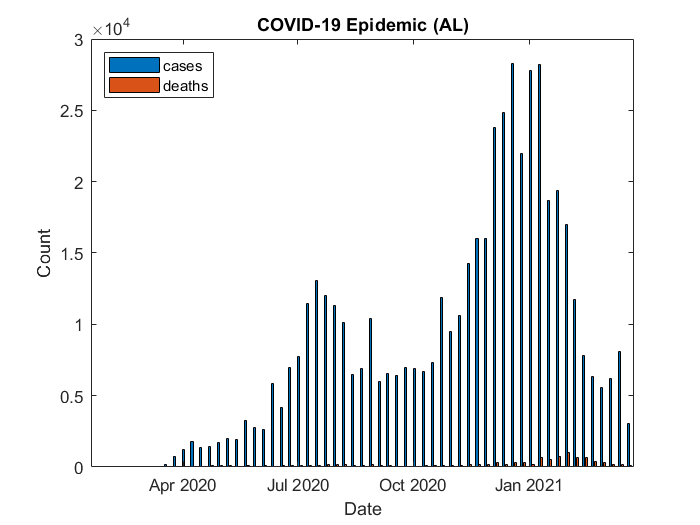

% Alabama data
file = 'al_covid.csv';
N = 4903185;

% read dates
dates = readvars(file);
ndays = length(dates);

% weekly data
al = week_tab(file);
week = al.week;
week_dates = linspace(dates(1),dates(end),week(end));
counts = [al.cases al.deaths];

% plot alongside infections
figure
bar(week_dates,counts)
title('COVID-19 Epidemic (AL)')
xlabel('Date')
ylabel('Count')
legend('cases','deaths','Location','northwest')

## Fit an SIR model to the data 

- Use the maximum weekly deaths as the peak of the infection.  

- Plot the infection curve in the same figure as the bar graph.  

- Plot the SIR curves together in one figure. 

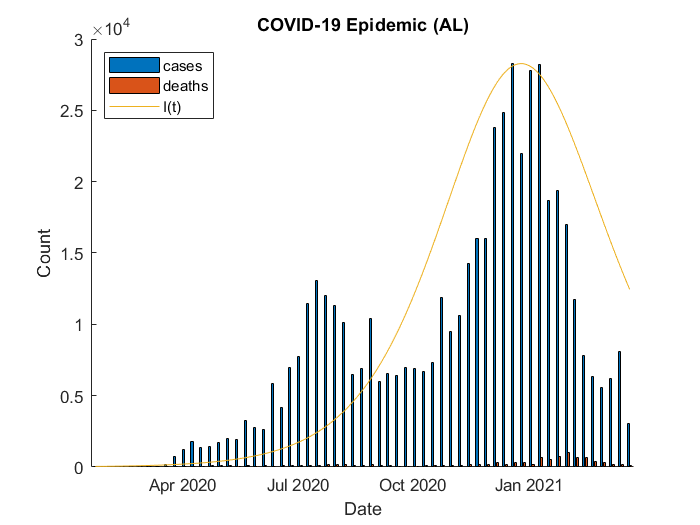

[~, curve, k, a]=sir_fit(file,N);
% plot alongside infections
figure
hold on
bar(week_dates,counts)
plot(dates,curve(:,2))
title('COVID-19 Epidemic (AL)')
xlabel('Date')
ylabel('Count')
legend('cases','deaths','I(t)','Location','northwest')
hold off

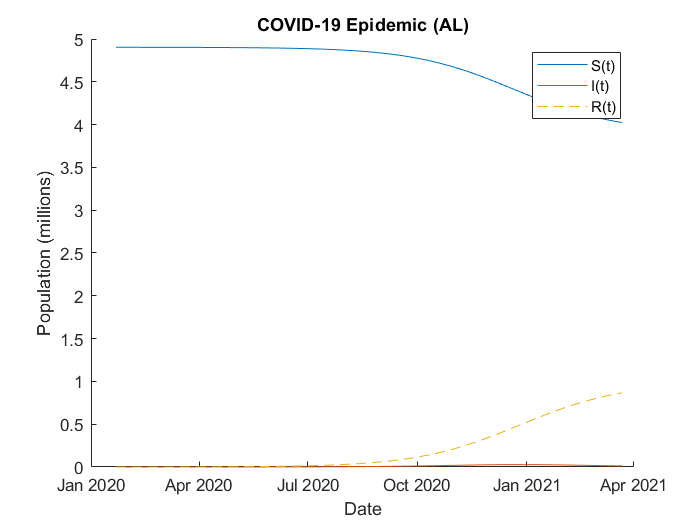


% plot SIR curve
curve = curve./1e6;
figure
hold on
title('COVID-19 Epidemic (AL)')
xlabel('Date')
ylabel('Population (millions)')
plot(dates,curve(:,1))
plot(dates,curve(:,2))
plot(dates,curve(:,3),'--')
legend('S(t)','I(t)','R(t)')
hold off

## Describe the characteristics of the fitted model. 

- Determine the expected “heard immunity” proportion 𝑠 ∗ . 

- Determine the contact rate 𝑎 and the recovery rate 𝑘. 

- Compare and contrast your calculated model with official estimates  from outside sources.

% susceptible equilibrium
i0 = 39/N;
s0 = 1-i0;
R0 = k/a;
K = i0+s0-R0*log(s0);
iprime = @(s,i) -1+R0./s; % i'(s) = di/ds
i_one = @(s) -s+R0*log(s)+K; % i(s) function
s_guess = 0.2; %initial guess for Newton's method
 
% Newton's method with 10 iterations
s_star = newton_m(i_one,iprime,s_guess,10)

s_star =    0.796831140979762


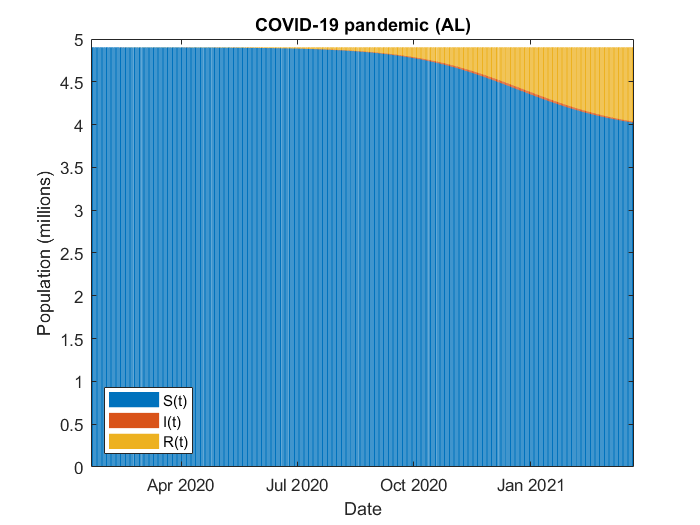



% stacked bar graph
figure
bar(dates, curve,'stacked')
legend('S(t)','I(t)','R(t)','Location','southwest')
xlabel('Date')
ylabel('Population (millions)')
title('COVID-19 pandemic (AL)')

The model predicts a "herd immunity" of about 21% (`s_star = 0.796831140979762`), meaning that about 21% of people will be infected with the disease before it is eradicated. 